# Example 1: Case of a  clamped-free beam

Computation of displacement repsonse of a cantilever beam subjected to a random load, represented here by an uncorrelated white noise.

## Definition of the geometry

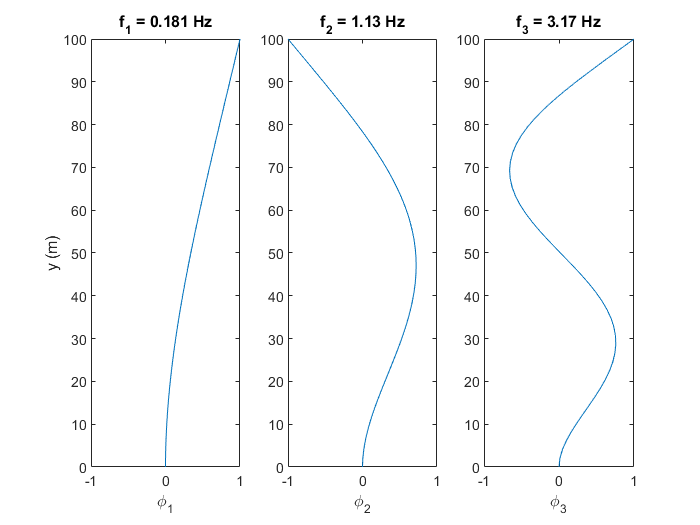

clearvars;close all;clc;
geometry.L = 100; % beam length (m)
geometry.E = 2.1e11; % Young Modulus (Pa)
geometry.nu = 0.3; % Poisson ratio
geometry.rho = 7850; % density (kg/m^3)

% case of a cylinder
Nnodes = 50; % numbe rof ndoes
D = geometry.L/20; % beam diameter (m)   --> beam is symmetrical around axes y and z
Iy = pi.*D.^4./64;
Ix = pi.*D.^4./64;
geometry.I = Iy; % affectation of quadratic moment
geometry.y = linspace(0,geometry.L ,Nnodes); 
V = pi.*D.^2*geometry.L;
geometry.m = geometry.rho.*V./geometry.L;

% Number of modes
Nmodes =3; % number of mode wanted
BC = 2;% clamped-free beam

[phi,wn] = eigenModes(geometry,BC,Nmodes);

figure
for ii=1:Nmodes,
    subplot(1,Nmodes,ii)
    box on;grid on
    plot(phi(ii,:),geometry.y);
    if ii==1,  ylabel('y (m)'); end
    title(['f_',num2str(ii),' = ',num2str(wn(ii)/2/pi,3),' Hz']); 
    xlim([-1,1])
    
    xlabel(['\phi_',num2str(ii)]);
end
set(gcf,'color','w')

## Computation of the displacement response in the time domain

N = 1.5e4;
fs = 20;
dt = 1/fs;
t = [0:N-1].*dt;
fprintf(['total duration is ',num2str(t(end),4),' s \n'])

total duration is 750 s 


zetaStruct = 0.005*ones(1,Nmodes);
z = geometry.y; % nodes of the beam in the z direction
m = geometry.m;
Fy = 1e5.*randn(Nnodes,N); % Force normal to the beam main axis in the y direction

% Impulse load
% Fy = zeros(Nnodes,N); Fy(end,100)=1e6;


tic
[Do1] = dynaResp_TD(m,z,phi,wn,zetaStruct,Fy,t,'method','Newmark');
toc

Elapsed time is 2.108364 seconds.



tic
[Do2] = dynaResp_TD(m,z,phi,wn,zetaStruct,Fy,t,'method','RK4');
toc

Elapsed time is 1.589512 seconds.


## Time series comparison

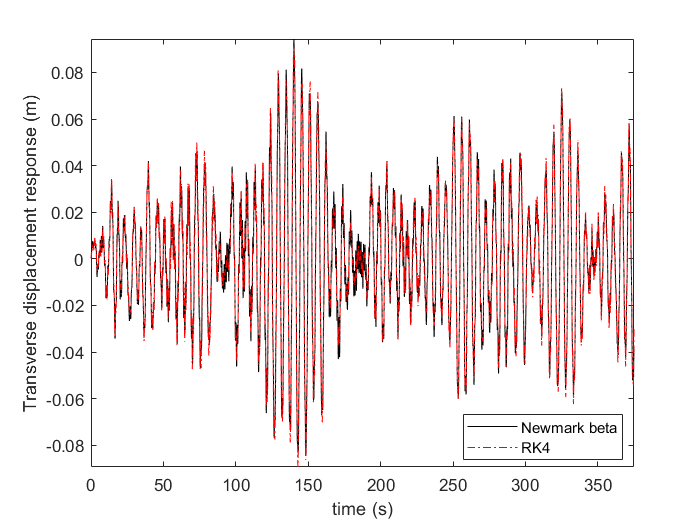



clf;close all;
figure
plot(t(1:round(N/2)),Do1(end,1:round(N/2)),'k',t(1:round(N/2)),Do2(end,1:round(N/2)),'r-.');
xlabel('time (s)')
ylabel('Transverse displacement response (m)')
axis tight
set(gcf,'color','w')
legend('Newmark beta','RK4','location','best')

## PSD  displacement comparison

The plot of the PSD shows that the RK4 method tends to respect the eigenfrequencies used as input, but as the mode number increases, the damping is not properly represented. On the other hand, the newmark-beta method provides good damping estimates but the eigenfrequencies are biased toward lower values  as the mode number increases.

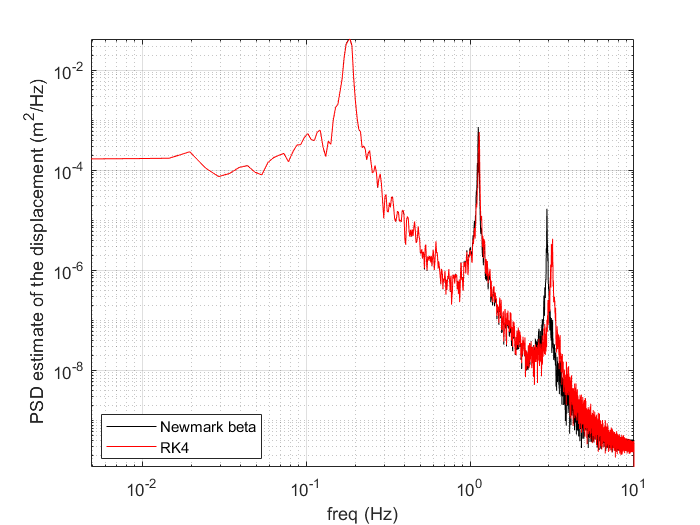

[S1,f]=pwelch(Do1(end,:),[],[],[],fs);
[S2,f]=pwelch(Do2(end,:),[],[],[],fs);

clf;close all;
figure
loglog(f,S1,'k',f,S2,'r');

xlabel('freq (Hz)')
ylabel(' PSD estimate of the displacement (m^2/Hz)')
axis tight
set(gcf,'color','w')
legend('Newmark beta','RK4','location','best')
grid on
grid minor